% read in data
% pixel 
shrinkpics = load("shrinkdf.mat");
zoompics = load("zoomdf.mat");

% labels
shrinklabel = load("shrinkdf_labels.mat");
shrinklabel = shrinklabel.label;
zoomlabel = load("zoomdf_labels.mat");
zoomlabel = zoomlabel.labelz;

% jpgs
shrinkpicfiles = load("shrinkdf_orig_file_name.mat");
shrinkpicfiles = shrinkpicfiles.orig_file_name;
zoompicfiles = load("zoomdf_orig_file_name.mat");
zoompicfiles = zoompicfiles.orig_file_namez;



%%%%%%% SHRINKED DATA 8 breed LDA
X = normalize(double(shrinkpics.img_total));
breeds = unique(shrinklabel);


%%%%%%% PCA to reduce dim before multiclass LDA
X = X- mean(X, 1);
k = 100;
[U, S] = svds(X, k);
X = U .* diag(S)'; % k principal components


%%%%% LDA on all 8 breeds (7d)
cv = cvpartition(shrinklabel,'HoldOut',0.3, 'Stratify', true); % 70-30 train-test balanced
idx = cv.test;
X_Test  = X(idx,:);
X_Train = X(~idx,:);
label_Train = shrinklabel(~idx);
label_Test = shrinklabel(idx);


C_bengal = X_Train(label_Train == "Bengal",:);
C_bombay = X_Train(label_Train == "Bombay",:);
C_himalayan = X_Train(label_Train == "Himalayan",:);
C_mainecoon = X_Train(label_Train == "Maine_Coon",:);
C_russianblue = X_Train(label_Train == "Russian_Blue",:);
C_snowshoe = X_Train(label_Train == "SnowShoe",:);
C_tabby = X_Train(label_Train == "Tabby",:);
C_tuxedo = X_Train(label_Train == "Tuxedo",:);

m = mean(X_Train,1);
m_bengal = mean(C_bengal ,1);
m_bombay = mean(C_bombay,1);
m_himalayan = mean( C_himalayan   ,1);
m_mainecoon = mean( C_mainecoon   ,1);
m_russianblue = mean( C_russianblue   ,1);
m_snowshoe = mean(C_snowshoe    ,1);
m_tabby = mean( C_tabby   ,1);
m_tuxedo = mean(C_tuxedo    ,1);

Mtilde = [ sqrt(size(C_bengal,1))*(m_bengal-m) ; 
    sqrt(size(C_bombay,1))*(m_bombay-m);
    sqrt(size(C_himalayan,1))*(m_himalayan-m) ; 
    sqrt(size(C_mainecoon,1))*(m_mainecoon-m); 
    sqrt(size(C_russianblue,1))*(m_russianblue-m);
    sqrt(size(C_snowshoe,1))*(m_snowshoe-m);
    sqrt(size(C_snowshoe,1))*(m_snowshoe-m);
    sqrt(size(C_tabby,1))*(m_tabby-m);
    sqrt(size(C_tuxedo,1))*(m_tuxedo-m)];

S_b = Mtilde' * Mtilde;

Xtilde = [C_bengal - m_bengal ; C_bombay - m_bombay ; C_himalayan - m_himalayan ;
            C_mainecoon - m_mainecoon; C_russianblue - m_russianblue ; C_snowshoe - m_snowshoe;
            C_tabby - m_tabby; C_tuxedo - m_tuxedo];
S_w = Xtilde' * Xtilde;

cond(S_w)

ans = 267.3678

[V,D] = eigs(S_b,S_w);
v1 = V(:,1);
v1 = normalize(v1);
v2 = V(:,2);
v2 = normalize(v2);

% lda project coeffs v1
lda_proj_bengal_v1 = v1' * C_bengal';
lda_proj_bombay_v1 = v1' * C_bombay';
lda_proj_himalayan_v1 = v1' * C_himalayan';
lda_proj_mainecoon_v1 = v1' * C_mainecoon';
lda_proj_russianblue_v1 = v1' * C_russianblue';
lda_proj_snowshoe_v1 = v1' * C_snowshoe';
lda_proj_tabby_v1 = v1' * C_tabby';
lda_proj_tuxedo_v1 = v1' * C_tuxedo';

% lda project coeffs v2
lda_proj_bengal_v2 = v2' * C_bengal';
lda_proj_bombay_v2 = v2' * C_bombay';
lda_proj_himalayan_v2 = v2' * C_himalayan';
lda_proj_mainecoon_v2 = v2' * C_mainecoon';
lda_proj_russianblue_v2 = v2' * C_russianblue';
lda_proj_snowshoe_v2 = v2' * C_snowshoe';
lda_proj_tabby_v2 = v2' * C_tabby';
lda_proj_tuxedo_v2 = v2' * C_tuxedo';

group = [repmat("Bengal",length(lda_proj_bengal_v2),1)', ...
    repmat("Bombay",length(lda_proj_bombay_v2),1)', ...
    repmat("Himalayan",length(lda_proj_himalayan_v2),1)', ...
    repmat("Maine_Coon",length(lda_proj_mainecoon_v2),1)', ...
    repmat("Russian_Blue",length(lda_proj_russianblue_v2),1)', ...
    repmat("SnowShoe",length(lda_proj_snowshoe_v2),1)', ...
    repmat("Tabby",length(lda_proj_tabby_v2),1)', ...
    repmat("Tuxedo",length(lda_proj_tuxedo_v2),1)'];


l_alt = length(lda_proj_himalayan_v2) + length(lda_proj_mainecoon_v2) + ...
    length(lda_proj_russianblue_v2) + length(lda_proj_snowshoe_v2) + length(lda_proj_tabby_v2) + ...
    length(lda_proj_tuxedo_v2);

group_alt = [repmat("Other",length(lda_proj_bengal_v2),1)', ...
    repmat("Bombay",length(lda_proj_bombay_v2),1)', ...
    repmat("Other",l_alt,1)'];

l_alt2 = length(lda_proj_himalayan_v2) + length(lda_proj_mainecoon_v2) + ...
    length(lda_proj_russianblue_v2);

length(lda_proj_snowshoe_v2)

ans = 490

length(lda_proj_tuxedo_v2)

ans = 490

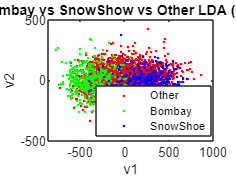


group_alt2 = [repmat("Other",length(lda_proj_bengal_v2),1)', ...
    repmat("Bombay",length(lda_proj_bombay_v2),1)', ...
    repmat("Other",l_alt2,1)', ...
    repmat("SnowShoe",length(lda_proj_snowshoe_v2),1)', ...
    repmat("Other",length(lda_proj_tabby_v2)+length(lda_proj_tuxedo_v2),1)'];


ys = [lda_proj_bengal_v2, lda_proj_bombay_v2, lda_proj_himalayan_v2, lda_proj_mainecoon_v2,...
    lda_proj_russianblue_v2, lda_proj_snowshoe_v2, lda_proj_tabby_v2, lda_proj_tuxedo_v2] ;
xs = [lda_proj_bengal_v1, lda_proj_bombay_v1, lda_proj_himalayan_v1, lda_proj_mainecoon_v1, ...
    lda_proj_russianblue_v1, lda_proj_snowshoe_v1, lda_proj_tabby_v1, lda_proj_tuxedo_v1];

gscatter(xs',ys', group_alt2');
title('Bombay vs SnowShow vs Other LDA (shrink)');
xlabel('v1');
ylabel('v2');
%saveas(gcf, '8 Breed LDA (shrink).png');
%saveas(gcf, 'Bombay vs 7 other Breeds LDA (shrink).png');
saveas(gcf, 'Bombay vs SnowShow vs Other LDA (shrink).png');

%%%%%%% ZOOM DATA 8 breed LDA
X = normalize(double(zoompics.img_totalz));
breeds = unique(zoomlabel);


%%%%%%% PCA to reduce dim before multiclass LDA
X = X- mean(X, 1);
k = 100;
[U, S] = svds(X, k);
X = U .* diag(S)'; % k principal components


%%%%% LDA on all 8 breeds (7d)
cv = cvpartition(zoomlabel,'HoldOut',0.3, 'Stratify', true); % 70-30 train-test balanced
idx = cv.test;
X_Test  = X(idx,:);
X_Train = X(~idx,:);
label_Train = zoomlabel(~idx);
label_Test = zoomlabel(idx);


C_bengal = X_Train(label_Train == "Bengal",:);
C_bombay = X_Train(label_Train == "Bombay",:);
C_himalayan = X_Train(label_Train == "Himalayan",:);
C_mainecoon = X_Train(label_Train == "Maine_Coon",:);
C_russianblue = X_Train(label_Train == "Russian_Blue",:);
C_snowshoe = X_Train(label_Train == "SnowShoe",:);
C_tabby = X_Train(label_Train == "Tabby",:);
C_tuxedo = X_Train(label_Train == "Tuxedo",:);

m = mean(X_Train,1);
m_bengal = mean(C_bengal ,1);
m_bombay = mean(C_bombay,1);
m_himalayan = mean( C_himalayan   ,1);
m_mainecoon = mean( C_mainecoon   ,1);
m_russianblue = mean( C_russianblue   ,1);
m_snowshoe = mean(C_snowshoe    ,1);
m_tabby = mean( C_tabby   ,1);
m_tuxedo = mean(C_tuxedo    ,1);

Mtilde = [ sqrt(size(C_bengal,1))*(m_bengal-m) ; 
    sqrt(size(C_bombay,1))*(m_bombay-m);
    sqrt(size(C_himalayan,1))*(m_himalayan-m) ; 
    sqrt(size(C_mainecoon,1))*(m_mainecoon-m); 
    sqrt(size(C_russianblue,1))*(m_russianblue-m);
    sqrt(size(C_snowshoe,1))*(m_snowshoe-m);
    sqrt(size(C_tabby,1))*(m_tabby-m);
    sqrt(size(C_tuxedo,1))*(m_tuxedo-m)];

S_b = Mtilde' * Mtilde;

Xtilde = [C_bengal - m_bengal ; C_bombay - m_bombay ; C_himalayan - m_himalayan ;

ans = 783.0843

            C_mainecoon - m_mainecoon; C_russianblue - m_russianblue ; C_snowshoe - m_snowshoe;
            C_tabby - m_tabby; C_tuxedo - m_tuxedo];
S_w = Xtilde' * Xtilde;

cond(S_w)

[V,D] = eigs(S_b,S_w);
v1 = V(:,1);
v1 = normalize(v1);
v2 = V(:,2);
v2 = normalize(v2);

% lda project coeffs v1
lda_proj_bengal_v1 = v1' * C_bengal';
lda_proj_bombay_v1 = v1' * C_bombay';
lda_proj_himalayan_v1 = v1' * C_himalayan';
lda_proj_mainecoon_v1 = v1' * C_mainecoon';
lda_proj_russianblue_v1 = v1' * C_russianblue';
lda_proj_snowshoe_v1 = v1' * C_snowshoe';
lda_proj_tabby_v1 = v1' * C_tabby';
lda_proj_tuxedo_v1 = v1' * C_tuxedo';

% lda project coeffs v2
lda_proj_bengal_v2 = v2' * C_bengal';
lda_proj_bombay_v2 = v2' * C_bombay';
lda_proj_himalayan_v2 = v2' * C_himalayan';
lda_proj_mainecoon_v2 = v2' * C_mainecoon';
lda_proj_russianblue_v2 = v2' * C_russianblue';
lda_proj_snowshoe_v2 = v2' * C_snowshoe';
lda_proj_tabby_v2 = v2' * C_tabby';
lda_proj_tuxedo_v2 = v2' * C_tuxedo';

group = [repmat("Bengal",length(lda_proj_bengal_v2),1)', ...
    repmat("Bombay",length(lda_proj_bombay_v2),1)', ...
    repmat("Himalayan",length(lda_proj_himalayan_v2),1)', ...
    repmat("Maine_Coon",length(lda_proj_mainecoon_v2),1)', ...
    repmat("Russian_Blue",length(lda_proj_russianblue_v2),1)', ...
    repmat("SnowShoe",length(lda_proj_snowshoe_v2),1)', ...
    repmat("Tabby",length(lda_proj_tabby_v2),1)', ...
    repmat("Tuxedo",length(lda_proj_tuxedo_v2),1)'];


l_alt = length(lda_proj_himalayan_v2) + length(lda_proj_mainecoon_v2) + ...
    length(lda_proj_russianblue_v2) + length(lda_proj_snowshoe_v2) + length(lda_proj_tabby_v2) + ...
    length(lda_proj_tuxedo_v2);

group_alt = [repmat("Other",length(lda_proj_bengal_v2),1)', ...
    repmat("Bombay",length(lda_proj_bombay_v2),1)', ...
    repmat("Other",l_alt,1)'];

l_alt2 = length(lda_proj_himalayan_v2) + length(lda_proj_mainecoon_v2) + ...
    length(lda_proj_russianblue_v2);

length(lda_proj_snowshoe_v2)

ans = 489

length(lda_proj_tuxedo_v2)

ans = 490

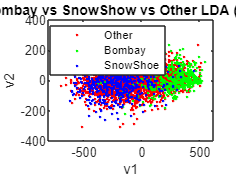


group_alt2 = [repmat("Other",length(lda_proj_bengal_v2),1)', ...
    repmat("Bombay",length(lda_proj_bombay_v2),1)', ...
    repmat("Other",l_alt2,1)', ...
    repmat("SnowShoe",length(lda_proj_snowshoe_v2),1)', ...
    repmat("Other",length(lda_proj_tabby_v2)+length(lda_proj_tuxedo_v2),1)'];


ys = [lda_proj_bengal_v2, lda_proj_bombay_v2, lda_proj_himalayan_v2, lda_proj_mainecoon_v2,...
    lda_proj_russianblue_v2, lda_proj_snowshoe_v2, lda_proj_tabby_v2, lda_proj_tuxedo_v2] ;
xs = [lda_proj_bengal_v1, lda_proj_bombay_v1, lda_proj_himalayan_v1, lda_proj_mainecoon_v1, ...
    lda_proj_russianblue_v1, lda_proj_snowshoe_v1, lda_proj_tabby_v1, lda_proj_tuxedo_v1];

gscatter(xs',ys', group_alt2');
title('Bombay vs SnowShow vs Other LDA (zoom)');
xlabel('v1');
ylabel('v2');
%saveas(gcf, '8 Breed LDA (zoom).png');
%saveas(gcf, 'Bombay vs 7 other Breeds LDA (zoom).png');
saveas(gcf, 'Bombay vs SnowShow vs Other LDA (zoom).png');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% PCA to detect outliers

for i = 1:length(breeds)
    breed = breeds(i)
    breed_idx = shrinklabel == breed;

    k = 1;
    Xtilde = X(breed_idx,:) - mean(X(breed_idx,:),1);
    [U,S,V] = svds(Xtilde, k); % k is the reduced dimension
    Y = U .* diag(S)';
    scatter(1:length(Y),Y);
    title(strcat('1d PCA ',breed));
    xlabel("index");
    ylabel("principal component");
    saveas(gcf, strcat(strcat(string(i),strcat("_1dpca_", breed)),'.png'))

    k = 2;
    Xtilde = X(breed_idx,:) - mean(X(breed_idx,:),1);
    [U,S,V] = svds(Xtilde, k); % k is the reduced dimension
    Y = U .* diag(S)';
    scatter(Y(:,1), Y(:,2));
    title(strcat('2d PCA ',breed))
    xlabel("principal component v1");
    ylabel("principal component v2 ");
    saveas(gcf, strcat(strcat(string(i),strcat("_2dpca_", breed)),'.png'))
end


%% BENGALS
breed = breeds(1) 
breed_idx = shrinklabel == breed;

k = 200;
    Xtilde = X(breed_idx,:) - mean(X(breed_idx,:),1);
    [U,S,V] = svds(Xtilde, k); % k is the reduced dimension
    Y = U .* diag(S)';

D_bengal = double.empty(); %distances
for row=1:length(Y)
    D_bengal(row) = norm(Y(row,:));
end

[M,I] = max(D_bengal)

%%%%% Plot
outliers_idx = D_bengal > quantile(D_bengal,.75);
sum(outliers_idx)
uglyduckling = ones(length(Y),1);
uglyduckling(outliers_idx) = 0;
gscatter(Y(:,1), Y(:,2), uglyduckling)
title("Bengal")
gscatter(1:length(Y), Y(:,1), uglyduckling)
title("Bengal")

bengal_idx = shrinklabel == "Bengal";
breed_files = shrinkpicfiles(bengal_idx);
filenames_out_bengal = breed_files(outliers_idx);
filenames_in_bengal = breed_files(~outliers_idx);
%%%%%
%% HIMALAYAN
breed = breeds(3) 
breed_idx = shrinklabel == breed;

k = 200;
    Xtilde = X(breed_idx,:) - mean(X(breed_idx,:),1);
    [U,S,V] = svds(Xtilde, k); % k is the reduced dimension
    Y = U .* diag(S)';

D_hima = double.empty(); %distances
for row=1:length(Y)
    D_hima(row) = norm(Y(row,:));
end

[M,I] = max(D_hima)
%%%% Plot Himalayan outliers
outliers_idx = D_hima > quantile(D_hima,.75);
sum(outliers_idx)
uglyduckling = ones(length(Y),1);
uglyduckling(outliers_idx) = 0;
gscatter(Y(:,1), Y(:,2), uglyduckling)
title("Hima")
gscatter(1:length(Y), Y(:,1), uglyduckling)
title("Hima")


%%%%%%%%% TRY LDA with simple outlier rules
%%%% creating data to compare BENGALS and HIMALAYANS
outliers_idx_bengal = D_bengal > quantile(D_bengal,.75);
outliers_idx_hima = D_hima > quantile(D_hima,.75);

bengal_idx = shrinklabel == "Bengal";
hima_idx = shrinklabel == "Himalayan";

X_bengals = X(bengal_idx, :);
X_bengals = X_bengals(~outliers_idx_bengal, :); %remove "outliers"

X_hima = X(hima_idx, :);
X_hima = X_hima(~outliers_idx_hima, :); %remove "outliers"

% BENGALS Cross validation (train: 70%, test: 30%)
cv = cvpartition(size(X_bengals,1),'HoldOut',0.3);
idx = cv.test;
X_bengals_Train = X_bengals(~idx,:);
X_bengals_Test  = X_bengals(idx,:);

% HIMA Cross validation (train: 70%, test: 30%)
cv = cvpartition(size(X_hima,1),'HoldOut',0.3);
idx = cv.test;
X_hima_Train = X_hima(~idx,:);
X_hima_Test  = X_hima(idx,:);


labs_Train = [repelem("Bengal", size(X_bengals_Train,1)), ...
    repelem("Himalayan", size(X_hima_Train,1))]';
labs_Test = [repelem("Bengal", size(X_bengals_Test,1)), ...
    repelem("Himalayan", size(X_hima_Test,1))]';

X_Train = [X_bengals_Train;X_hima_Train];
X_Test = [X_bengals_Test;X_hima_Test];
%%%%%%%%%%%%%%%%%%%%%%%
%PCA first to help with singularity of S_w
% PCA CODE
k = 100;
Xtilde = X_Train - mean(X_Train,1);
[U,S,V] = svds(Xtilde, k); % k is the reduced dimension
Y_Train = U .* diag(S)';

k = 100;
Xtilde = X_Test - mean(X_Test,1);
[U,S,V] = svds(Xtilde, k); % k is the reduced dimension
Y_Test = U .* diag(S)';


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% LDA now
% (2 categories implies at most one discriminative direction)

C_bengals = Y_Train(labs_Train == "Bengal",:); % classes
C_hima = Y_Train(labs_Train == "Himalayan",:);

m_1 = mean(C_bengals ,1);
m_2 = mean(C_hima ,1);

% compute within class scatter matrix
S_w = zeros(size(k,k)); % init
numrows_bengals = size(C_bengals ,1);
numrows_hima = size(C_hima ,1);

for i = 1:numrows_bengals
    S_w = S_w + (C_bengals(i,:) - m_1)' * (C_bengals(i,:) - m_1);
end
for i = 1:numrows_hima
    S_w = S_w + (C_hima(i,:) - m_2)' * (C_hima(i,:) - m_2);
end

cond(S_w) % not badly ill-conditioned


% most discriminitive line
v1 = S_w \ (m_1-m_2)';
v1 = normalize(v1);

% lda project coeffs
lda_proj_bengals = v1' * C_bengals';
lda_proj_hima = v1' * C_hima';

% plotting
group = [repmat("Bengal",length(lda_proj_bengals),1)', ...
    repmat("Himalayan",length(lda_proj_hima),1)'];
gscatter(1:length(group),[lda_proj_bengals, lda_proj_hima] , group');

xlabel('index')
ylabel('LDA projection coefficient')
title("LDA Train")



%%%%% TESTING

true_labs = labs_Test;
lda_proj_Test = v1' * Y_Test';
threshold = -30;

pred_labs = string.empty();
for i=1:length(lda_proj_Test)
    if lda_proj_Test(i) > threshold
        pred_labs(i) = "Bengal";
    else
        pred_labs(i) = "Himalayan";
    end
end

pred_labs = pred_labs';

sum(true_labs == pred_labs)/314

confusionmat(true_labs,pred_labs)

%%%%%%%%%%%%%%%%% ZOOM Pic pairwise LDA now
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% LDA TO COMPARE ANY 2 
X = normalize(double(zoompics.img_totalz));
breeds = unique(zoomlabel);
label = zoomlabel;

% optionally remove outliers here

for i = 1:length(breeds)
    breed1 = breeds(i);
    for j = 1:length(breeds)
        if i >= j
            continue
        end
        breed2 = breeds(j);
        [breed1,breed2]
        idx = logical((label==breed1) + (label==breed2));
        X_reduced = X(idx, :);
        label_reduced = label(idx);
        % PCA k = 100
        k=100;
        X_reduced = X_reduced- mean(X_reduced, 1);
        [U, S] = svds(X_reduced, k);
        Y = U .* diag(S)';

        % LDA (train and test)
        cv = cvpartition(label_reduced,'HoldOut',0.3, 'Stratify', true); % 70-30 train-test balanced
        idx = cv.test;
        Y_Test  = Y(idx,:);
        Y_Train = Y(~idx,:);
        label_Test = label_reduced(idx);
        label_Train = label_reduced(~idx);

        C_1 = Y_Train(label_Train == breed1,:); % classes
        C_2 = Y_Train(label_Train == breed2,:);
        m_1 = mean(C_1 ,1);
        m_2 = mean(C_2 ,1);

        % compute within class scatter matrix
        S_w = zeros(size(k,k)); % init     
        numrows_1 = size(C_1 ,1);      
        numrows_2 = size(C_2 ,1);

        for p = 1:numrows_1
            S_w = S_w + (C_1(p,:) - m_1)' * (C_1(p,:) - m_1);      
        end      
        for p = 1:numrows_2        
            S_w = S_w + (C_2(p,:) - m_2)' * (C_2(p,:) - m_2);       
        end

        cond(S_w) 

        % most discriminitive line
        v1 = S_w \ (m_1-m_2)';
        v1 = normalize(v1);

        % lda project coeffs
        lda_proj_1 = v1' * C_1';
        lda_proj_2 = v1' * C_2';

        % plotting
        group = [repmat(breed1,length(lda_proj_1),1)', ...
                repmat(breed2,length(lda_proj_2),1)'];
        gscatter(1:length(group),[lda_proj_1, lda_proj_2] , group');
        text = strcat( "1d LDA for ", strcat(strcat(breed1," vs "),breed2));
        title(text);
        xlabel("index");
        ylabel("v1");
        saveas(gcf, strcat(text,'.png'));

        %prediction accuracy

    end
end

%%%%%%%%%%%%%%%%% SHRINK Pic pairwise LDA now
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% LDA TO COMPARE ANY 2 
X = normalize(double(shrinkpics.img_total));
breeds = unique(shrinklabel);
label = shrinklabel;

% optionally remove outliers here

for i = 1:length(breeds)
    breed1 = breeds(i);
    for j = 1:length(breeds)
        if i >= j
            continue
        end
        breed2 = breeds(j);
        [breed1,breed2]
        idx = logical((label==breed1) + (label==breed2));
        X_reduced = X(idx, :);
        label_reduced = label(idx);
        % PCA k = 100
        k=100;
        X_reduced = X_reduced- mean(X_reduced, 1);
        [U, S] = svds(X_reduced, k);
        Y = U .* diag(S)';

        % LDA (train and test)
        cv = cvpartition(label_reduced,'HoldOut',0.3, 'Stratify', true); % 70-30 train-test balanced
        idx = cv.test;
        Y_Test  = Y(idx,:);
        Y_Train = Y(~idx,:);
        label_Test = label_reduced(idx);
        label_Train = label_reduced(~idx);

        C_1 = Y_Train(label_Train == breed1,:); % classes
        C_2 = Y_Train(label_Train == breed2,:);
        m_1 = mean(C_1 ,1);
        m_2 = mean(C_2 ,1);

        % compute within class scatter matrix
        S_w = zeros(size(k,k)); % init     
        numrows_1 = size(C_1 ,1);      
        numrows_2 = size(C_2 ,1);

        for p = 1:numrows_1
            S_w = S_w + (C_1(p,:) - m_1)' * (C_1(p,:) - m_1);      
        end      
        for p = 1:numrows_2        
            S_w = S_w + (C_2(p,:) - m_2)' * (C_2(p,:) - m_2);       
        end

        cond(S_w) 

        % most discriminitive line
        v1 = S_w \ (m_1-m_2)';
        v1 = normalize(v1);

        % lda project coeffs
        lda_proj_1 = v1' * C_1';
        lda_proj_2 = v1' * C_2';

        % plotting
        group = [repmat(breed1,length(lda_proj_1),1)', ...
                repmat(breed2,length(lda_proj_2),1)'];
        gscatter(1:length(group),[lda_proj_1, lda_proj_2] , group');
        text = strcat( "1d LDA for ", strcat(strcat(breed1," vs "),breed2));
        title(text);
        xlabel("index");
        ylabel("v1");
        saveas(gcf, strcat(text,'.png'));

        %prediction accuracy

    end
end



% LDA on Bombay, Hima, SnowShoe, and Tabby  (4 group 3d)
shrinkpics = load("shrinkdf.mat");
label = shrinklabel;


X = normalize(double(shrinkpics.img_total));
idx = logical((label == "Bombay") + (label == "Himalayan") + (label == "SnowShoe") + (label == "Tabby"));
X = X(idx,:);
label = label(idx);

%%%%%%% PCA to reduce dim before multiclass LDA
X = X- mean(X, 1);
k = 100;
[U, S] = svds(X, k);
X = U .* diag(S)'; % k principal components



%%%%%%%% LDA
C_bombay = X(label == "Bombay",:);
C_himalayan = X(label == "Himalayan",:);
C_snowshoe = X(label == "SnowShoe",:);
C_tabby = X(label == "Tabby",:);

m = mean(X,1);
m_bombay = mean(C_bombay,1);
m_himalayan = mean( C_himalayan   ,1);
m_snowshoe = mean(C_snowshoe    ,1);
m_tabby = mean( C_tabby   ,1);

Mtilde = [ 
    sqrt(size(C_bombay,1))*(m_bombay-m);
    sqrt(size(C_himalayan,1))*(m_himalayan-m) ; 
    sqrt(size(C_snowshoe,1))*(m_snowshoe-m);
    sqrt(size(C_tabby,1))*(m_tabby-m); ];

S_b = Mtilde' * Mtilde;

Xtilde = [C_bombay - m_bombay ; C_himalayan - m_himalayan ; C_snowshoe - m_snowshoe;
            C_tabby - m_tabby];
S_w = Xtilde' * Xtilde;

cond(S_w)

ans = 257.8999


[V,D] = eigs(S_b,S_w);
v1 = V(:,1);
v1 = normalize(v1);
v2 = V(:,2);
v2 = normalize(v2);
v3 = V(:,3);
v3 = normalize(v3);


% lda project coeffs v1
lda_proj_bombay_v1 = v1' * C_bombay';
lda_proj_himalayan_v1 = v1' * C_himalayan';
lda_proj_snowshoe_v1 = v1' * C_snowshoe';
lda_proj_tabby_v1 = v1' * C_tabby';

% lda project coeffs v2
lda_proj_bombay_v2 = v2' * C_bombay';
lda_proj_himalayan_v2 = v2' * C_himalayan';
lda_proj_snowshoe_v2 = v2' * C_snowshoe';
lda_proj_tabby_v2 = v2' * C_tabby';

% lda project coeffs v3
lda_proj_bombay_v3 = v3' * C_bombay';
lda_proj_himalayan_v3 = v3' * C_himalayan';
lda_proj_snowshoe_v3 = v3' * C_snowshoe';
lda_proj_tabby_v3 = v3' * C_tabby';


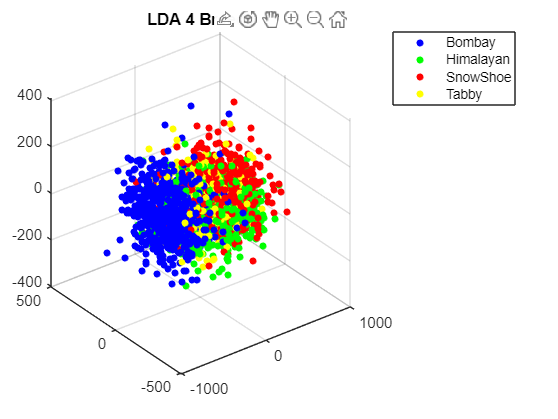

figure;
set(gca, 'fontsize', 11)
plot3(lda_proj_bombay_v1 , lda_proj_bombay_v2, ...
    lda_proj_bombay_v3, '.b', 'MarkerSize', 14 );
hold on
plot3(lda_proj_himalayan_v1 , lda_proj_himalayan_v2, ...
    lda_proj_himalayan_v3, '.g', 'MarkerSize', 14 );
hold on
plot3(lda_proj_snowshoe_v1 , lda_proj_snowshoe_v2, ...
    lda_proj_snowshoe_v3, '.r', 'MarkerSize', 14 );
hold on
plot3(lda_proj_tabby_v1 , lda_proj_tabby_v2, ...
    lda_proj_tabby_v3, '.y', 'MarkerSize', 14 );

grid on
legend("Bombay","Himalayan", "SnowShoe","Tabby")
title('LDA 4 Breeds')
hold off